clear all
close all
clc

addpath('dace')
Ms = csvread('./data/mysqlResult_transfer1.csv', 1, 0)
Mx = csvread('./data/mysqlResult_transfer2.csv', 1, 0)
Mtrain = csvread('./data/train.csv')
Mval = csvread('./data/val.csv')



n=50;
idx = randperm(454);%将所有数随机打乱
idx=idx(1:n);%取前n个
Mtrain=Mx(idx,:);%训练集
Mval = Mx;
Mval(idx,:)=[];%测试集

Ms_x=Ms(1:800,1:10)
Ms_y=Ms(1:800,11)
Mtrain_x=Mtrain(:,1:10)
Mtrain_y=Mtrain(:,11)
Mval_x=Mval(:,1:10)
Mval_y=Mval(:,11)

[dmodel,dmc,dmd]=cokriging2(Mtrain_x,Mtrain_y,Ms_x,Ms_y,@regpoly0,@corrgauss,1e-6,1e2)
cok=predict_cok2(Mval_x,dmodel)
%co_k=sum(abs(c-Mval_y))/(454-n)
%meap = mean(abs((observed - predicted)./observed))*100
meap_co=mean(abs((Mval_y-cok)./Mval_y))*100
krig = dacefit(Mtrain_x,Mtrain_y,@regpoly0,@corrgauss,1e-6,1e-3,20);
kg = predictor(Mval_x,krig)
meap_k=mean(abs((Mval_y-kg)./Mval_y))*100


%Ms_y_m=horzcat(Ms_y,Ms_y,Ms_y,Ms_y,Ms_y,Ms_y,Ms_y,Ms_y,Ms_y,Ms_y)
%Mtrain_y_m=horzcat(Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y,Mtrain_y)
%Mval_y_m=horzcat(Mval_y,Mval_y,Mval_y,Mval_y,Mval_y,Mval_y,Mval_y,Mval_y,Mval_y,Mval_y)


train_nums=[2,3,4,5,6,7,8,9,10,15,20,30,50,100,150,200]

train_nums =      2     3     4     5     6     7     8     9    10    15    20    30    50   100   150   200


train_nums=[220,240,260,280,300]
ref_nums=[500,600,700,800]

ref_nums =    500   600   700   800


all=ones(48,6)

all =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


cnt=1

cnt = 1

for i=1:16
    n=train_nums(i)
    for j=1:4
        r=ref_nums(j)
        [co,k]=compute_mape(n,r)
        all(cnt,1:6)=[n,r,co,k,co-k,50]
        cnt=cnt+1
    end
end

n = 2

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.

co = 12.8825

k = 17.1836

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 2

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.

co = 12.3103

k = 17.1038

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 3

r = 700

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.

co = 12.7074

k = 16.8879

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 4

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.

co = 13.5173

k = 18.5090

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 5

n = 3

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.thet

co = 12.8818

k = 16.1228

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 6

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+

co = 12.3040

k = 17.1062

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 7

r = 700

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =

co = 12.7153

k = 15.6340

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 8

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta 

co = 13.5205

k = 18.0004

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 9

n = 4

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02


co = 12.8984

k = 17.6044

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cnt = 10

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dm

co = 12.3086

k = 14.8963

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 11

r = 700

dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dm

co = 12.6915

k = 15.5246

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 12

r = 800

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.t

co = 13.5210

k = 15.0200

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 13

n = 5

r = 500

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.06
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.

co = 12.9182

k = 15.3068

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 14

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
d

co = 12.3483

k = 15.6618

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 15

r = 700

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dm

co = 12.7245

k = 15.2488

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 16

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.th

co = 13.6335

k = 16.3995

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 17

n = 6

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.027
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e

co = 13.0393

k = 15.5089

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 18

r = 600

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.022
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta 

co = 12.4517

k = 15.5543

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 19

r = 700

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.018
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e

co = 12.7389

k = 14.9337

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 20

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =

co = 13.5484

k = 16.6914

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 21

n = 7

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.028
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.032
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.067
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1

co = 12.9774

k = 16.3174

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 22

r = 600

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.032
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc

co = 12.5645

k = 15.4705

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 23

r = 700

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  1e+02
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1

co = 12.7627

k = 15.7898

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 24

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta = 

co = 13.5800

k = 15.9252

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 25

n = 8

r = 500

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.028
dmd.theta =  1e+02
dmc.theta =  0.067
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  16
dmd.thet

co = 13.2595

k = 14.5584

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 26

r = 600

dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
d

co = 12.4308

k = 15.7078

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 27

r = 700

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.06
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  1e+02
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.057
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.032
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.028
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta

co = 12.8539

k = 15.1664

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 28

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.the

co = 13.6181

k = 14.9518

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 29

n = 9

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.067
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.016
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.067
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.057
dmd.theta

co = 13.2213

k = 15.5186

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 30

r = 600

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02


co = 12.4122

k = 15.2942

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 31

r = 700

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta 

co = 12.8439

k = 15.1114

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 32

r = 800

dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta

co = 13.5390

k = 15.1955

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 33

n = 10

r = 500

dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.th

co = 13.1752

k = 14.6349

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 34

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta = 

co = 12.5505

k = 15.8190

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 35

r = 700

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.025
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.thet

co = 12.7893

k = 15.6119

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 36

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.06
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta = 

co = 13.5298

k = 14.7061

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 37

n = 15

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.057
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dm

co = 13.3935

k = 15.0001

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 38

r = 600

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.64
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.057
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.

co = 12.8707

k = 14.9162

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 39

r = 700

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1

co = 12.7738

k = 14.9130

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 40

r = 800

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.022
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.05
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.th

co = 13.6876

k = 15.9776

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 41

n = 20

r = 500

dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dm

co = 13.1271

k = 14.8043

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 42

r = 600

dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.thet

co = 12.3985

k = 15.1005

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 43

r = 700

dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.071
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.t

co = 12.8805

k = 15.0815

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 44

r = 800

dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.04
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  1e+02
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
d

co = 13.6447

k = 14.9090

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 45

n = 30

r = 500

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd

co = 12.8830

k = 14.2055

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 46

r = 600

dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta = 

co = 12.4707

k = 14.6307

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 47

r = 700

dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.063
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.067
dmd.theta =  1e+02
dmc.theta =  0.06
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.th

co = 12.9266

k = 14.2982

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 48

r = 800

dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.08
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  0.32
dm

co = 13.4576

k = 14.7071

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 49

n = 50

r = 500

dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  16


co = 12.8095

k = 14.1561

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 50

r = 600

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.thet

co = 12.2164

k = 14.0942

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 51

r = 700

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta 

co = 12.5627

k = 13.8891

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 52

r = 800

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.64
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.thet

co = 13.4542

k = 14.0533

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 53

n = 100

r = 500

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.64
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  2.6
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.t

co = 11.8948

k = 13.2424

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 54

r = 600

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc

co = 11.8171

k = 13.4177

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 55

r = 700

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.th

co = 12.3924

k = 13.3809

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 56

r = 800

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  1e+02
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.45
dmd.theta =  1e+02
dmc.theta =  0.38
dmd.theta =  1e+02
dmc.theta =  16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.4
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.

co = 13.3447

k = 13.3963

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 57

n = 150

r = 500

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
d

co = 11.6080

k = 12.5982

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 58

r = 600

dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dm

co = 11.7840

k = 12.6030

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 59

r = 700

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
d

co = 12.3696

k = 12.5922

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 60

r = 800

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.51
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
d

co = 13.2813

k = 12.5926

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 61

n = 200

r = 500

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dm

co = 11.3307

k = 11.8553

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 62

r = 600

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.1
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.36
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dm

co = 11.5946

k = 12.1990

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 63

r = 700

dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.43
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
d

co = 12.3170

k = 11.8687

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 64

r = 800

dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.32
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.16
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
dmc.theta =  0.25
dmd.theta =  1e+02
d

co = 13.2163

k = 12.0636

all =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


cnt = 65

name='试验记录';
%转置
%m1=m';
m1=all

m1 =     2.0000  500.0000   12.8825   17.1836   -4.3011   50.0000
    2.0000  600.0000   12.3103   17.1038   -4.7935   50.0000
    2.0000  700.0000   12.7074   16.8879   -4.1805   50.0000
    2.0000  800.0000   13.5173   18.5090   -4.9917   50.0000
    3.0000  500.0000   12.8818   16.1228   -3.2410   50.0000
    3.0000  600.0000   12.3040   17.1062   -4.8022   50.0000
    3.0000  700.0000   12.7153   15.6340   -2.9187   50.0000
    3.0000  800.0000   13.5205   18.0004   -4.4800   50.0000
    4.0000  500.0000   12.8984   17.6044   -4.7060   50.0000
    4.0000  600.0000   12.3086   14.8963   -2.5877   50.0000


%表头
various={'train_num','ref_num','co_kg','kg','minus','rand_num'};
%表的内容
result_table=table(m1(:,1),m1(:,2),m1(:,3),m1(:,4),m1(:,5),m1(:,6),'VariableNames',various);
%创建csv表格
writetable(result_table, 'result.csv')


%% 生成表格行列名称，m行n列
str1='结果';str2='实验';
m=48;n=6;
column_name=strcat(str1,num2str((1:n)'));
row_name=strcat(str2,num2str((1:m)'));
%column_name=strcat(1,['训练个数','参考个数','协同克里','单克里格','两个作差','采样次数']')


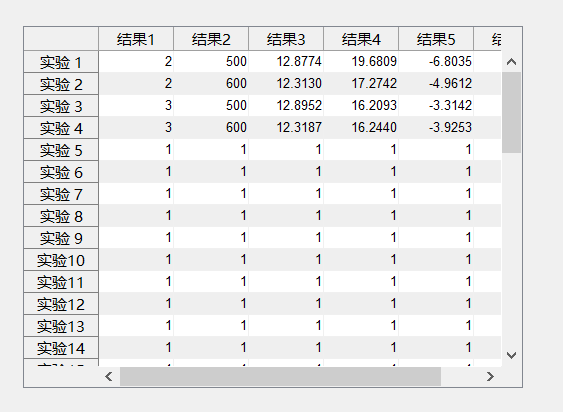

%% 表格作图
set(figure(1),'position',[2 200 450 330]);
uitable(gcf,'Data',all,'Position',[20 20 400 290],'Columnname',column_name,'Rowname',row_name);

clear all
close all
clc
format long g 
addpath('dace')
%% 测试均值在各个数据集上的表现
train_n=2000

train_n =    200


val_n=200

val_n =    200


r=600

r =    600


addpath('dace');
Ms = csvread('./data/mysqlResult_transfer1.csv', 1, 0);
Mx = csvread('./data/sac_AllNumeric(1).csv', 1, 0);
size_mx=size(Mx)

size_mx =        62523          60


all_num=size_mx(1)

all_num =        62523


feature_size=size_mx(2)-1

feature_size =     59


label_pos=size_mx(2)

label_pos =     60



idx = randperm(all_num);%将所有数随机打乱
train_idx=idx(1:train_n);%取前n个
val_idx=idx((train_n+1):(train_n+val_n))

val_idx =        56141         402       55361       58021       26605       31828       40088       40079       50226        6259       25800       11807        2697       53412       10061       38632       37563       45581       48548       43006       60372       38502       33080        1055       52439       23003       37781       52373       59458       21211       39075       57077       62113        1734       39665       28438       21672        1419       24836       20917       60857        4673       11685       49828       32862       56778        3852       37304       45373        8117       52633       44974       10109       40308        3785       14298       54652        7643       27778       59718       51514        6428        5018       42380       59148       42524       18482       38979       58894       61953       16781       33058       36643        9854       30552       56896       10528         396       24592       12390       15580       57594      

Mtrain=Mx(train_idx,:);%训练集
Mval = Mx(val_idx,:);%测试集

Ms_x=Ms(1:r,1:10);
Ms_y=Ms(1:r,11);
Mtrain_x=Mtrain(:,1:feature_size);
Mtrain_y=Mtrain(:,label_pos);
Mval_x=Mval(:,1:feature_size);
Mval_y=Mval(:,label_pos);

mean_train=mean(Mx(:,label_pos))

mean_train =           7.29313228731882


meap = mean(abs((Mx(:,label_pos) - mean_train)./Mx(:,label_pos)))*100

meap =           245.233127635698



matrix_var_col=var(Mx(:,label_pos))

matrix_var_col =            325.12011658574


matrix_std_col=std(Mx(:,label_pos),1)

matrix_std_col =           18.0309433080324


%[dmodel,dmc,dmd]=cokriging2(Mtrain_x,Mtrain_y,Ms_x,Ms_y,@regpoly0,@corrgauss,1e-6,1e2);
%cok=predict_cok2(Mval_x,dmodel);
%co_k=sum(abs(c-Mval_y))/(454-n)

krig = dacefit(Mtrain_x,Mtrain_y,@regpoly0,@corrgauss,1e-6,1e-3,20);
kg = predictor(Mval_x,krig);
meap_k=mean(abs((Mval_y-kg)./Mval_y))*100;
